% Clear workspace and close figures
clear;
close all;
clc;

%% Parameters
N = 10000;           % Sample size
rho_between = 0;   % Pearson correlation between risk_scores1 and risk_scores2

% Desired c-indices
desired_cindex1 = 0.59;  % Fixed c-index for risk_scores1
desired_cindices2 = [0.59, 0.57, 0.55, 0.53]; % c-indices for risk_scores2

% Initialize weights
num_weights = 100;
weights = linspace(0, 1, num_weights);  % Weight for risk_scores2 varies from 0 to 1

% Initialize matrix to store c-indices
c_indices = zeros(num_weights, length(desired_cindices2));

% Find Pearson correlation for risk_scores1 that yields desired c-index
rho_surv1 = find_pearson_for_cindex(desired_cindex1, N, rho_between, true);

% Initialize array to store rho_surv2 values
rho_surv2_values = zeros(size(desired_cindices2));

% Loop over each desired c-index for risk_scores2
for idx = 1:length(desired_cindices2)
    desired_cindex2 = desired_cindices2(idx);

    % Find Pearson correlation for risk_scores2 that yields desired c-index
    rho_surv2 = find_pearson_for_cindex(desired_cindex2, N, rho_between, false);
    rho_surv2_values(idx) = rho_surv2;

    % Generate data with the found rho_surv1 and rho_surv2
    [risk_scores, survival_times] = generate_synthetic_data_copula(N, rho_between, rho_surv1, rho_surv2);

    risk_scores1 = risk_scores(:,1);
    risk_scores2 = risk_scores(:,2);

    % Compute and verify c-indices
    c_idx1 = compute_c_index(risk_scores1, survival_times);
    c_idx2 = compute_c_index(risk_scores2, survival_times);
    fprintf('Desired c-index1: %.3f, Observed c-index1: %.3f\n', desired_cindex1, c_idx1);
    fprintf('Desired c-index2: %.3f, Observed c-index2: %.3f\n', desired_cindex2, c_idx2);

    % Loop over weights
    for i = 1:num_weights
        w = weights(i);
        % Compute weighted average of risk scores
        weighted_score = (1 - w) * risk_scores1 + w * risk_scores2;

        % Compute c-index with survival times
        c_idx = compute_c_index(weighted_score, survival_times);

        % Store the c-index
        c_indices(i, idx) = c_idx;
    end
end

Desired c-index1: 0.590, Observed c-index1: 0.591


Desired c-index2: 0.590, Observed c-index2: 0.591


Desired c-index1: 0.590, Observed c-index1: 0.591


Desired c-index2: 0.570, Observed c-index2: 0.571


Desired c-index1: 0.590, Observed c-index1: 0.591


Desired c-index2: 0.550, Observed c-index2: 0.551


Desired c-index1: 0.590, Observed c-index1: 0.591


Desired c-index2: 0.530, Observed c-index2: 0.531


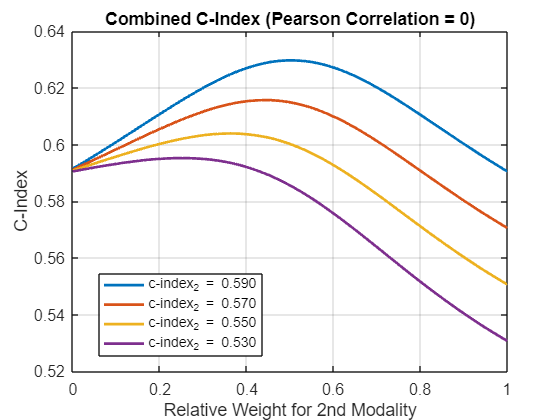


%% Plot c-index vs. Weight for Each desired_cindex2
figure;
plot(weights, c_indices, 'LineWidth', 2);
xlabel('Relative Weight for 2nd Modality', 'FontSize', 12);
ylabel('C-Index', 'FontSize', 12);
title('Combined C-Index (Pearson Correlation = 0)', 'FontSize', 14);
legend(arrayfun(@(c) sprintf('c-index_{2} = %.3f', c), desired_cindices2, 'UniformOutput', false), 'Location', 'Best');
grid on;
set(gca, 'FontSize', 12);


%% Functions


function rho_P = find_pearson_for_cindex(desired_cindex, N, rho_between, is_risk1)
    % Finds the Pearson correlation that results in the desired c-index
    % between a risk score and survival times.
    %
    % Parameters:
    %   desired_cindex - Desired c-index between risk score and survival times
    %   N              - Sample size
    %   rho_between    - Pearson correlation between risk_scores1 and risk_scores2
    %   is_risk1       - Boolean indicating whether to adjust rho for risk_scores1
    %
    % Returns:
    %   rho_P          - Pearson correlation that achieves the desired c-index

    tol = 1e-4;        % Tolerance for c-index difference
    max_iter = 20;     % Maximum number of iterations
    rho_P_low = 0.0;   % Lower bound for Pearson's rho
    rho_P_high = 0.9999; % Upper bound for Pearson's rho

    iter = 0;
    while iter < max_iter
        iter = iter + 1;
        rho_P = (rho_P_low + rho_P_high) / 2;

        % Set correlations
        if is_risk1
            rho_surv1 = rho_P;
            rho_surv2 = 0;
        else
            rho_surv1 = 0;
            rho_surv2 = rho_P;
        end

        % Generate data
        [risk_scores, survival_times] = generate_synthetic_data_copula(N, rho_between, rho_surv1, rho_surv2);
        risk_scores1 = risk_scores(:,1);
        risk_scores2 = risk_scores(:,2);

        % Select the appropriate risk score
        if is_risk1
            risk_score = risk_scores1;
        else
            risk_score = risk_scores2;
        end

        % Compute c-index
        c_idx = compute_c_index(risk_score, survival_times);

        % Check convergence
        cidx_diff = c_idx - desired_cindex;
        if abs(cidx_diff) < tol
            break;
        elseif cidx_diff > 0
            % Observed c-index is higher than desired; decrease rho_P
            rho_P_high = rho_P;
        else
            % Observed c-index is lower than desired; increase rho_P
            rho_P_low = rho_P;
        end
    end

    if iter == max_iter
        warning('Maximum iterations reached while finding Pearson correlation for desired c-index.');
    end
end

function [risk_scores, survival_times] = generate_synthetic_data_copula(N, rho_between, rho_surv1, rho_surv2)
    % Generates synthetic data using Gaussian copula with specified Pearson correlations.
    %
    % Parameters:
    %   N           - Number of samples
    %   rho_between - Pearson correlation between risk_scores1 and risk_scores2
    %   rho_surv1   - Pearson correlation between risk_scores1 and survival_times
    %   rho_surv2   - Pearson correlation between risk_scores2 and survival_times
    %
    % Returns:
    %   risk_scores     - Nx2 matrix of risk scores (risk_scores1 and risk_scores2)
    %   survival_times  - Exponentially distributed survival times

    %% Construct Gaussian Copula Correlation Matrix
    gauss_copula_corr = eye(3);
    gauss_copula_corr(1,2) = rho_between;
    gauss_copula_corr(2,1) = rho_between;
    gauss_copula_corr(1,3) = rho_surv1;
    gauss_copula_corr(3,1) = rho_surv1;
    gauss_copula_corr(2,3) = rho_surv2;
    gauss_copula_corr(3,2) = rho_surv2;

    %% Ensure the correlation matrix is positive definite
    [~, p] = chol(gauss_copula_corr);
    if p > 0
        % Adjust the correlation matrix slightly to make it positive definite
        gauss_copula_corr = nearestSPD(gauss_copula_corr);
    end

    %% Generate Samples from the Gaussian Copula
    % Generate samples from a multivariate normal distribution
    rng('default'); % For reproducibility
    Z = mvnrnd([0, 0, 0], gauss_copula_corr, N);

    % Convert the normal variables to uniform variables
    U = normcdf(Z);

    %% Transform Uniform Variables to Desired Marginals
    % Risk scores: Transform U(:,1) and U(:,2) to standard normal variables
    risk_scores1 = norminv(U(:,1));
    risk_scores2 = norminv(U(:,2));

    % Survival times: Transform U(:,3) to exponential distribution
    lambda = 1; % Rate parameter for the exponential distribution
    survival_times = -log(1 - U(:,3)) / lambda;

    %% Collect risk scores
    risk_scores = [risk_scores1, risk_scores2];
end

function Ahat = nearestSPD(A)
    % Find the nearest positive-definite matrix to input A
    % Higham's algorithm

    [~, S, V] = svd(A);
    H = V*S*V';
    Ahat = (A + A' + H + H') / 4;

    % Ensure symmetry
    Ahat = (Ahat + Ahat') / 2;

    % Check if Ahat is positive definite
    [~, p] = chol(Ahat);
    if p > 0
        % Add small perturbation to diagonal
        k = 0;
        spacing = eps(norm(A));
        while p > 0
            k = k + 1;
            mineig = min(eig(Ahat));
            Ahat = Ahat + (-mineig*k^2 + spacing) * eye(size(A));
            [~, p] = chol(Ahat);
        end
    end
end

function c_index = compute_c_index(risk_score, survival_time)
    % Efficiently computes the c-index between risk_score and survival_time
    %
    % Parameters:
    %   risk_score    - Vector of risk scores
    %   survival_time - Vector of survival times
    %
    % Returns:
    %   c_index       - Concordance index

    % Sort by survival time
    [survival_time_sorted, idx] = sort(survival_time);
    risk_score_sorted = risk_score(idx);

    % Compute concordant pairs using counts
    n = length(risk_score_sorted);
    concordant = 0;
    permissible = 0;

    for i = 1:n-1
        higher_risk = sum(risk_score_sorted(i) < risk_score_sorted(i+1:end));
        equal_risk = sum(risk_score_sorted(i) == risk_score_sorted(i+1:end)) / 2;
        concordant = concordant + higher_risk + equal_risk;
        permissible = permissible + n - i;
    end

    c_index = concordant / permissible;
end
